# Ejemplos solución mínimo cuadrática mediante descomposición QR

## Ejemplo 1 - Caso de una matriz cuadrada singular de rango máximo mal condicionada

disp('--------------------------------------------------------')

--------------------------------------------------------


disp('Ejemplo 1')

Ejemplo 1


disp('--------------------------------------------------------')

--------------------------------------------------------



rng(1);
A = rand(100);
A(:,2) = 7*A(:,5);
b =rand(100,1);

s = linsolve(A,b);

r = minimosQR(A,b);

r = 99


s'

ans = 1.0e+15 *

   -0.0000    0.5951    0.0000    0.0000   -4.1658    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000


r'

ans =    -0.7006   -0.0847    0.8294    0.2870    0.3887    1.7390   -0.2428   -0.2609    0.3212   -0.1758   -1.1939   -0.7770    0.4744   -0.0063    1.2949   -0.7954   -0.3867   -0.5141    0.3315   -1.7499   -0.8585    0.8529   -0.3161   -0.1416    0.5062    0.5797   -0.0729   -0.2677    0.6690   -0.2889   -0.4164    0.1192    0.1177    1.3970   -0.4453    0.6304    0.9671    0.4559   -0.6434    0.1009   -0.4868   -0.2030   -0.6878   -0.1421   -0.3911   -0.5640   -1.0588   -0.2935    0.9084    0.0481


A*r

ans =     0.0296
    0.0158
    1.6897
    0.1075
   -0.4014
    3.6073
    3.2040
    4.2070
    2.7008
   -0.1211


A*s

ans =     0.4681
   -0.2832
    0.7161
    1.0617
    0.0100
   -0.5964
    0.4461
    0.7862
    0.1414
    0.1767


b

b =     0.7655
    0.3082
    0.7354
    0.8122
    0.2367
    0.0628
    0.6220
    0.9439
    0.3477
    0.4336


Notamos que en este caso, se combina el hecho de que la matriz está mal condicionada con tener menos datos que incógnitas, dando como resultado un par de soluciones (tanto la real $s$ como la aproximada por el método $QR$) bastante alejadas de la real

f1 = figure 

f1 =   Figure (19) with properties:

      Number: 19
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [360 178 560 420]
       Units: 'pixels'

  Show all properties


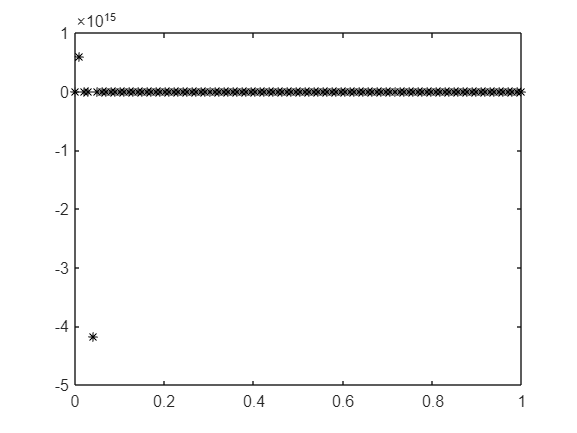

grid on
X = linspace(0,1,length(s));
plot(X,s,'*k')

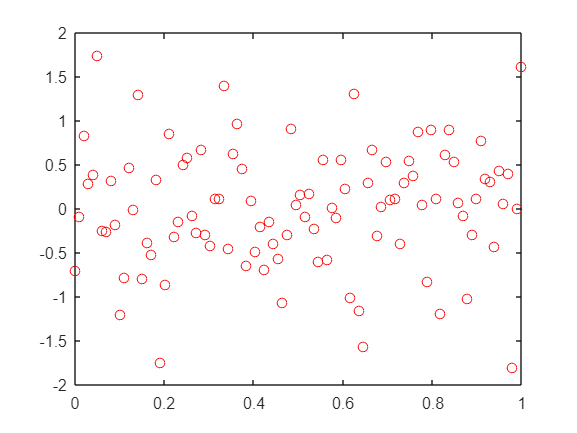

plot(X,r,'or')


disp('--------------------------------------------------------')

--------------------------------------------------------


disp('--------------------------------------------------------')

--------------------------------------------------------


En este caso, notamos que la dispersión de los datos es muy elevada para nuestra aproximación, mientras que la proporcionada por matlab se torna algo más estable respcto a oscilaciones de datos a excepción de dos picos en los datos

## Ejemplo 2 - Caso de una matriz cuadrada regular de rango máximo

disp('--------------------------------------------------------')

--------------------------------------------------------


disp('Ejemplo 2')

Ejemplo 2


disp('--------------------------------------------------------')

--------------------------------------------------------



rng(1)
A = rand(100);
b = rand(100,1)

b =     0.7655
    0.3082
    0.7354
    0.8122
    0.2367
    0.0628
    0.6220
    0.9439
    0.3477
    0.4336




s = linsolve(A,b);
r = minimosQR(A,b);

r = 100


dif = abs(s-r);
er = dif < 1e-12

er = 100×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1



s'

ans =    -0.8270   -0.5239    0.8175    0.8592   -0.2709    1.2408    0.6415    1.7346   -0.7089    0.1300   -0.1000    0.3764   -1.1400   -1.4753    0.9425    0.5402    1.4446   -0.4303   -0.6372   -0.1940    0.0675   -1.9698   -0.8356    0.6203   -0.9710   -0.2669    0.3342    0.8964   -0.0042   -0.1303    1.0805   -0.0060   -0.7489    0.2807    0.4000    1.2734    0.0872    0.7632    0.5749    0.7567   -0.7001    0.2209   -1.0209    0.2670   -0.9979   -0.4010   -0.5815   -0.3822   -1.5053   -0.1285


r'

ans =    -0.8270   -0.5239    0.8175    0.8592   -0.2709    1.2408    0.6415    1.7346   -0.7089    0.1300   -0.1000    0.3764   -1.1400   -1.4753    0.9425    0.5402    1.4446   -0.4303   -0.6372   -0.1940    0.0675   -1.9698   -0.8356    0.6203   -0.9710   -0.2669    0.3342    0.8964   -0.0042   -0.1303    1.0805   -0.0060   -0.7489    0.2807    0.4000    1.2734    0.0872    0.7632    0.5749    0.7567   -0.7001    0.2209   -1.0209    0.2670   -0.9979   -0.4010   -0.5815   -0.3822   -1.5053   -0.1285


A*r

ans =     0.7655
    0.3082
    0.7354
    0.8122
    0.2367
    0.0628
    0.6220
    0.9439
    0.3477
    0.4336


A*s

ans =     0.7655
    0.3082
    0.7354
    0.8122
    0.2367
    0.0628
    0.6220
    0.9439
    0.3477
    0.4336


b

b =     0.7655
    0.3082
    0.7354
    0.8122
    0.2367
    0.0628
    0.6220
    0.9439
    0.3477
    0.4336


En este caso, la solución proporcionada tiene una precisión con respecto a la solución real del orden de $10^{-12}$ 

f2 = figure

f2 =   Figure (10) with properties:

      Number: 10
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [360 178 560 420]
       Units: 'pixels'

  Show all properties


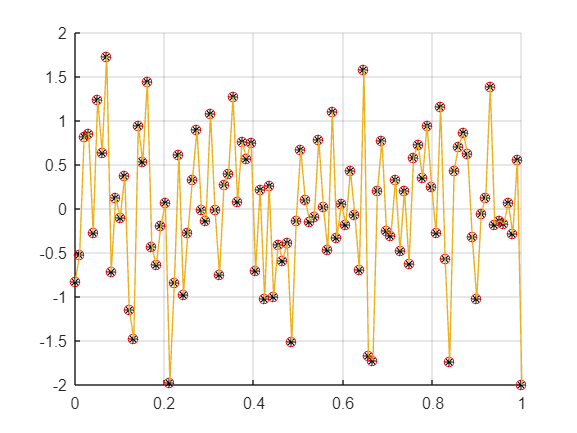

X = linspace(0,1,length(s));
grid on
hold on
plot(X, s, '*k')
plot(X,r,'or')
plot(X,s)% datos

disp('--------------------------------------------------------')

--------------------------------------------------------


disp('--------------------------------------------------------')

--------------------------------------------------------


Como se puede apreciar en la imagen, la distancia entre las soluciones es realmente

## Ejemplo 3 - Matriz con mas filas que columnas de rango n

disp('--------------------------------------------------------')

--------------------------------------------------------


disp('Ejemplo 3')

Ejemplo 3


disp('--------------------------------------------------------')

--------------------------------------------------------



rng(1);
A = rand(100);
A(1:30,:) = [];
b =rand(70,1);

s = linsolve(A,b);
r = minimosQR(A,b);

r = 70


dif = abs(s-r);
er = dif < 1e-1

er = 100×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0



s'

ans =     0.1982    0.1646         0         0    0.5419   -0.4478   -0.0874   -0.2356   -0.2007         0   -0.4377         0         0    0.2363    0.1917    0.2809    0.9894   -0.1396         0    0.6076         0         0         0    0.1743         0    0.1551   -0.6228    0.5277   -0.4400         0         0   -0.6258         0   -0.2350         0    0.2262    0.7334         0    0.5849   -0.1767   -0.2384         0    0.6898   -0.1683    0.4226         0   -0.0731         0         0         0


r'

ans =    -0.4490   -0.1901    0.3518    0.3654   -0.3079    0.6790    0.3741   -0.5997   -1.2539    0.8532    0.3785    0.0181   -0.0371    0.1506    0.1432   -0.4129    0.6378    1.0427   -0.9560    0.0406   -0.5225    0.1759   -0.2108   -0.4547    0.3132   -0.3083    0.2382    0.7886   -0.7670    0.9739   -0.0319   -0.2569    0.4489    0.3428   -1.1020   -0.9547   -1.1286   -0.2341    0.6529    0.1094   -0.1260    0.0279    1.1069   -0.7286    0.6137    0.2923    0.3873   -0.9882    0.8218    0.5716


A_r = A*r

A_r =     0.7655
    0.3082
    0.7354
    0.8122
    0.2367
    0.0628
    0.6220
    0.9439
    0.3477
    0.4336


A_s = A*s

A_s =     0.7655
    0.3082
    0.7354
    0.8122
    0.2367
    0.0628
    0.6220
    0.9439
    0.3477
    0.4336


b

b =     0.7655
    0.3082
    0.7354
    0.8122
    0.2367
    0.0628
    0.6220
    0.9439
    0.3477
    0.4336


Er1 = abs(b-A_s) <1e-14

Er1 = 70×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Er2 = abs(b-A_r) <1e-14

Er2 = 70×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Nuevamente, la soluciones se distancian bastante entre sí, pero a diferencia del ejemplo 1, en este caso la solución proporcionada en cada caso es bastante cercana a la solcución real.

f3 = figure

f3 =   Figure (22) with properties:

      Number: 22
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [360 178 560 420]
       Units: 'pixels'

  Show all properties


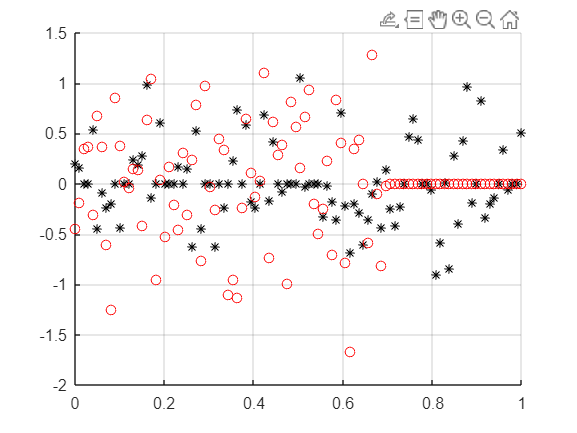

X = linspace(0,1,length(s));
grid on
hold on
plot(X, s, '*k')
plot(X,r,'or')

disp('--------------------------------------------------------')

--------------------------------------------------------


disp('--------------------------------------------------------')

--------------------------------------------------------


Aquí se parecia la dispersión y diferencia entre las soluciones